# TEST CAPACITA' UTILIZZATORE NELL' EFFETTUARE UNA TRAIETTORIA TARGET

clear all
clc

## CATTURA FOTOGRAMMI DEL TARGET

% Definizione della variabile stringa
targetID = 'cerchio';

% Percorso base
basePath = 'C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\dati test\test_accuratezza_user\tester1';

% Percorso completo del video
videoPath = fullfile(basePath, targetID, ['target_' targetID '.mpg']);

% Estrai il percorso senza l'ultimo elemento
[folder_target, ~, ~] = fileparts(videoPath);

% Lettura del video
video = VideoReader(videoPath);

% Creazione della directory per salvare i fotogrammi
outputDir = fullfile(basePath, targetID); % Usa targetID per creare la directory

% Controlla se la directory esiste, altrimenti creala
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

% Parametri
timeInterval = 1; % Intervallo di tempo in secondi per salvare i fotogrammi
frameRate = video.FrameRate; % Frame rate del video
frameInterval = round(timeInterval * frameRate); % Numero di frame tra due salvataggi

frameCount = 0;
savedFrameCount = 0;

disp('Inizio estrazione dei fotogrammi...');

Inizio estrazione dei fotogrammi...


% Ciclo sui frame del video
while hasFrame(video)
    % Leggi il frame corrente
    frame = readFrame(video);
    frameCount = frameCount + 1;
    
    % Salva solo ogni frameInterval-esimo fotogramma
    if mod(frameCount, frameInterval) == 0
        savedFrameCount = savedFrameCount + 1;
        % Nome del file immagine
        frameFile = fullfile(outputDir, sprintf('frame_%04d.png', savedFrameCount));
        
        % Salva il fotogramma come immagine PNG
        imwrite(frame, frameFile);
        fprintf('Salvato: %s\n', frameFile);
    end
end

Salvato: C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\dati test\test_accuratezza_user\tester1\quadrato\frame_0001.png
Salvato: C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\dati test\test_accuratezza_user\tester1\quadrato\frame_0002.png
Salvato: C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\dati test\test_accuratezza_user\tester1\quadrato\frame_0003.png
Salvato: C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\dati test\test_accuratezza_user\tester1\quadrato\frame_0004.png
Salvato: C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\Materiale\PROGETTO CALM\Caratterizzazione CALM\dati test\test_accuratezza_user\tester1\quad

## IDENTIFICA I BORDI DEL TARGET

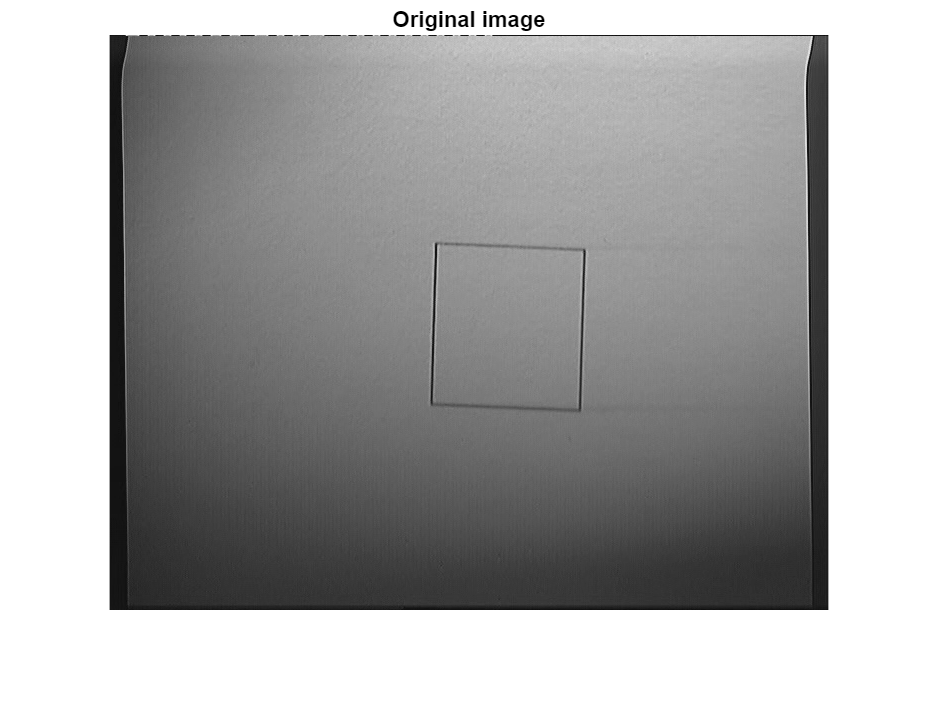

% Directory contenente i fotogrammi salvati
framesDir = outputDir; % Directory in cui i fotogrammi sono stati salvati

% Ottieni la lista di file nella directory
frameFiles = dir(fullfile(framesDir, '*.png')); % Sostituisci '*.png' con il formato corretto (ad esempio, '*.jpg')

% Controlla se ci sono file nella directory
if isempty(frameFiles)
    error('Non ci sono fotogrammi salvati nella directory specificata.');
end

% Ordina i file per nome
[~, idx] = sort({frameFiles.name}); % Ordina i file in ordine alfabetico
sortedFiles = frameFiles(idx);

% Ottieni l'ultimo file
lastFrameFile = fullfile(framesDir, sortedFiles(end).name);

% Leggi l'ultimo fotogramma
image = imread(lastFrameFile);
debug_on = true;

% Converti l'immagine in scala di grigi (se non lo è già)
if size(image, 3) == 3
    grayImage = rgb2gray(image);
else
    grayImage = image;
end

if debug_on
    figure
    imshow(grayImage)
    title('Original image')
end

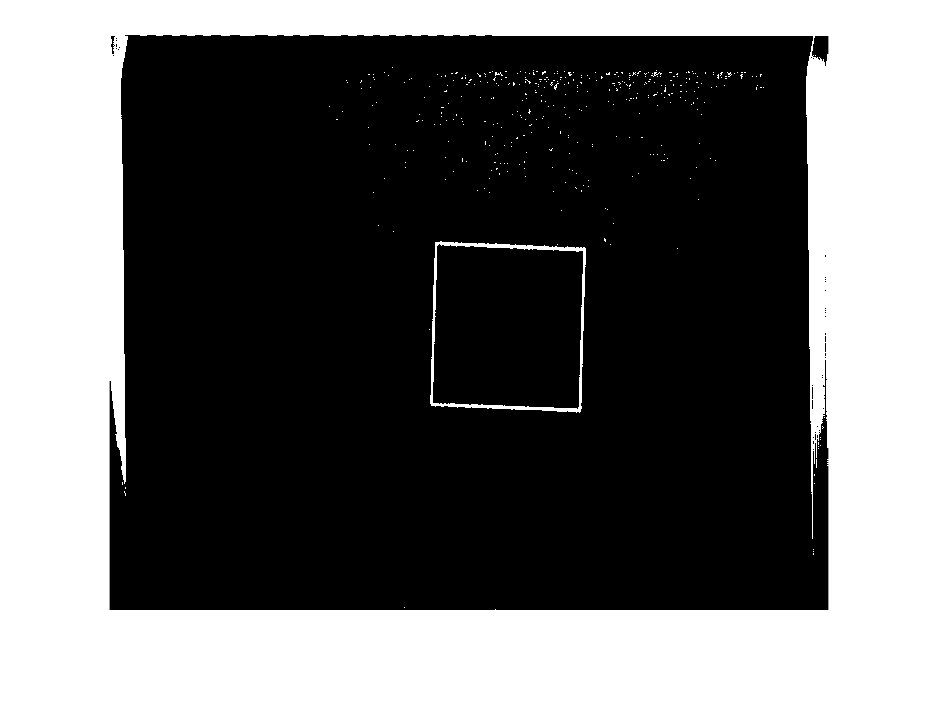

Icomplement = imcomplement(grayImage);
BW = imbinarize(Icomplement,"adaptive");

if debug_on
    figure
    imshow(BW)
end

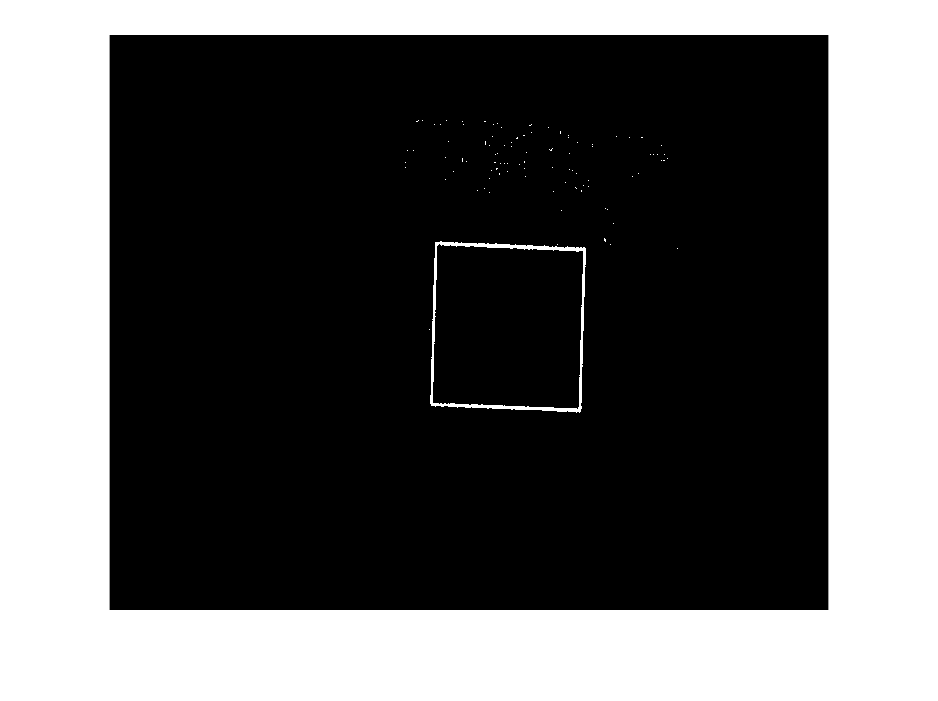

% Definisci una maschera per il quadrato centrale
[rows, cols] = size(grayImage);
centerMask = false(rows, cols);

% Definisci i limiti della regione centrale (ROI) 
centerRowStart = round(rows * 0.15);
centerRowEnd = round(rows * 0.70);
centerColStart = round(cols * 0.4);
centerColEnd = round(cols * 0.80);
centerMask(centerRowStart:centerRowEnd, centerColStart:centerColEnd) = true;
% Mantieni solo i bordi nella regione centrale
bordersCentral = BW & centerMask;

if debug_on
    figure
    imshow(bordersCentral)
end

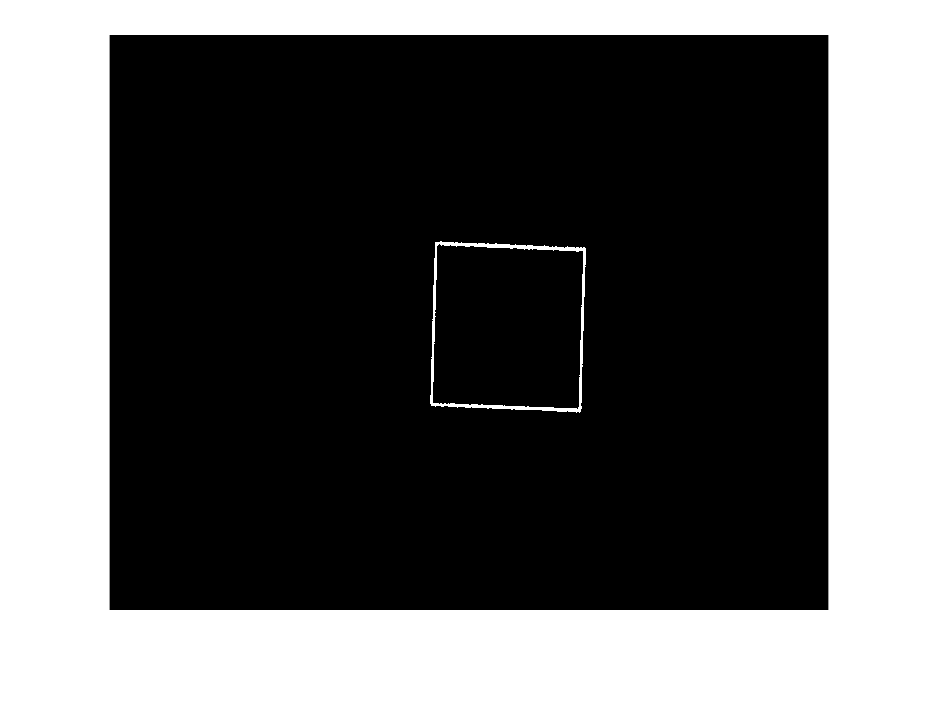

% Pulizia morfologica per eliminare artefatti
BWclean = bwmorph(bordersCentral, 'clean'); % Rimuove pixel isolati
% BWclean = bwmorph(BWclean, 'majority'); % Corregge piccoli buchi nei bordi
BWclean = imclose(BWclean, strel('square', 1)); % Chiude piccoli spazi nei bordi
% % Rimozione del rumore
BWclean = bwareaopen(BWclean, 50); % Rimuove oggetti con meno di 50 pixel

if debug_on
    figure
    imshow(BWclean)
end

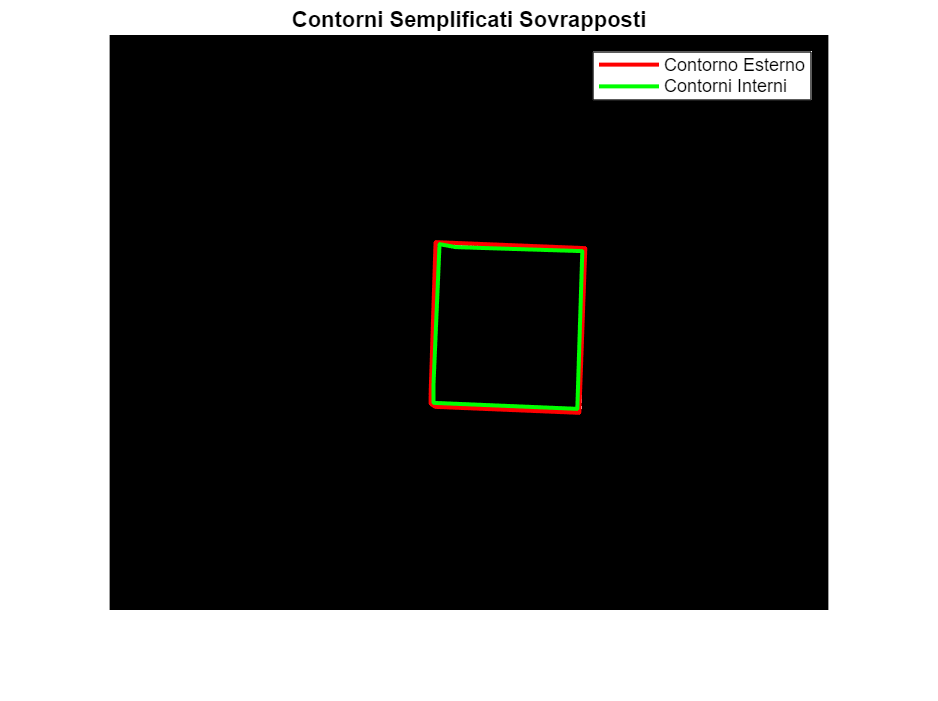

% Estrai i contorni con bwboundaries
boundaries = bwboundaries(BWclean, 'holes'); % 'holes' per includere contorni interni

% Contorno Esterno (Primo Contorno)
boundaryExternal = boundaries{1};
colExternal = boundaryExternal(:, 2);
rowExternal = boundaryExternal(:, 1);

% % Semplifica il contorno esterno usando Douglas-Peucker
tolerance = 0.009; % Tolleranza per semplificare i contorni
simplifiedExternal = reducepoly([colExternal, rowExternal], tolerance);

% Salva le coordinate del contorno esterno
externalCoords = simplifiedExternal;

% Contorni Interni (dal secondo in poi)
internalCoords = {}; % Inizializza cell array per i contorni interni

for k = 2:length(boundaries)
    boundaryInternal = boundaries{k};
    colInternal = boundaryInternal(:, 2);
    rowInternal = boundaryInternal(:, 1);
    
    % % Semplifica il contorno interno usando Douglas-Peucker
    simplifiedInternal = reducepoly([colInternal, rowInternal], tolerance);
    
    % Salva le coordinate semplificate del contorno interno
    internalCoords{end+1} = simplifiedInternal;
end

% Visualizza i risultati
figure;
imshow(BWclean);
title('Contorni Semplificati Sovrapposti');
hold on;

% Plot del contorno esterno
plot(externalCoords(:, 1), externalCoords(:, 2), 'r-', 'LineWidth', 2);

% Plot dei contorni interni
for k = 1:length(internalCoords)
    plot(internalCoords{k}(:, 1), internalCoords{k}(:, 2), 'g-', 'LineWidth', 2);
end

legend('Contorno Esterno', 'Contorni Interni');
hold off;

#### Interpola i bordi del target

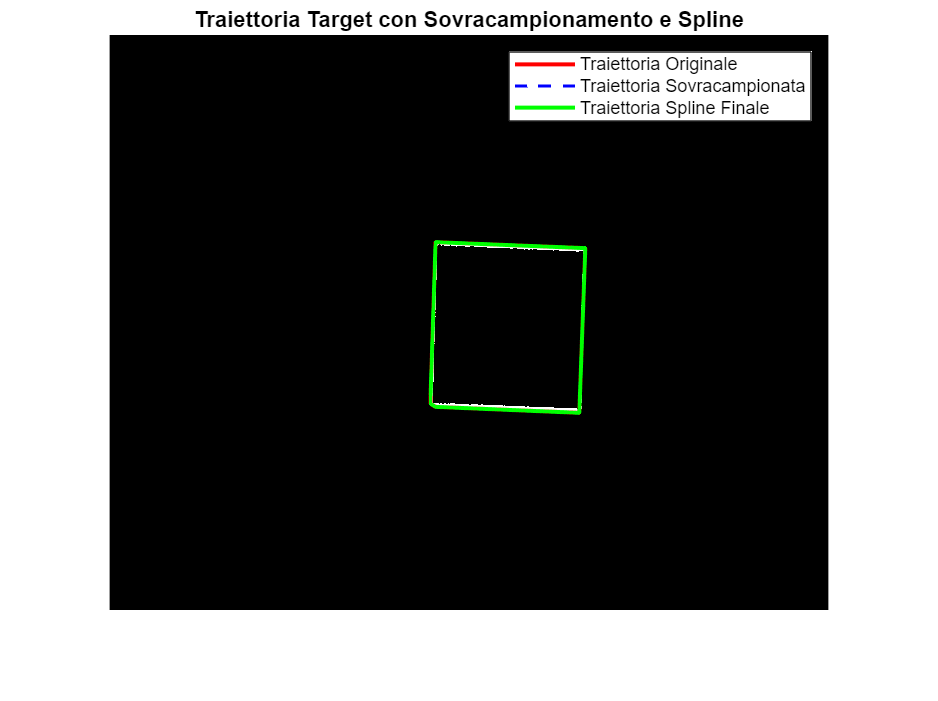

% % Carica le coordinate semplificate salvate
% load('contour_coordinates.mat'); % Carica externalCoords e internalCoords

% Seleziona il contorno target (es: contorno esterno)
trajectoryCoords = externalCoords;

% Passo 1: Sovracampionamento della traiettoria semplificata
numPoints = 100 * size(trajectoryCoords, 1); % Aumenta il numero di punti (ad esempio 5x)
tOriginal = 1:size(trajectoryCoords, 1);
tOversampled = linspace(1, size(trajectoryCoords, 1), numPoints);

xOversampled = interp1(tOriginal, trajectoryCoords(:,1), tOversampled, 'linear');
yOversampled = interp1(tOriginal, trajectoryCoords(:,2), tOversampled, 'linear');

% Passo 2: Interpolazione spline sulla traiettoria sovracampionata
tSpline = linspace(1, numPoints, numPoints * 2); % Ulteriore interpolazione spline
xSpline = interp1(1:numPoints, xOversampled, tSpline, 'spline');
ySpline = interp1(1:numPoints, yOversampled, tSpline, 'spline');

% Visualizza la traiettoria target
figure;
imshow(BWclean);
title('Traiettoria Target con Sovracampionamento e Spline');
hold on;

% Plot della traiettoria originale semplificata
plot(trajectoryCoords(:,1), trajectoryCoords(:,2), 'r-', 'LineWidth', 2);

% Plot della traiettoria sovracampionata
plot(xOversampled, yOversampled, 'b--', 'LineWidth', 1.5);

% Plot della traiettoria spline finale
plot(xSpline, ySpline, 'g-', 'LineWidth', 2);
legend('Traiettoria Originale', 'Traiettoria Sovracampionata', 'Traiettoria Spline Finale');
hold off;

% Salva la traiettoria target come coordinate
% trajectoryTarget = [xInterp', yInterp'];
% save('trajectory_target.mat', 'trajectoryTarget');

## PROIETTA IL TARGET NEL MONDO

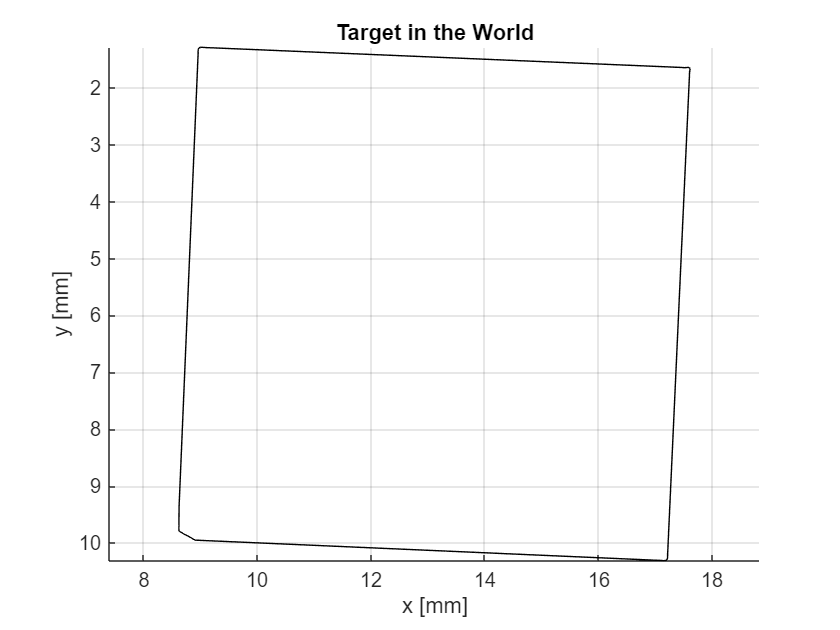

load("C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\" + ...
    "Materiale\PROGETTO CALM\Caratterizzazione CALM\Calibration_steps\pixels_to_world_coordinates\" + ...
    "improvement_test\calibrazione_720_576\dati di calibrazione\calm_camera_calibration.mat");

intrinsics = calm_camera_calibration.Instrinsics_params;
extrinsics = calm_camera_calibration.Extrinsics_params;

load("C:\Users\mdilucchio\OneDrive - Fondazione Istituto Italiano Tecnologia\Desktop\CALM\" + ...
    "Materiale\PROGETTO CALM\Caratterizzazione CALM\Calibration_steps\pixels_to_world_coordinates\" + ...
    "improvement_test\calibrazione_720_576\CameraCalibratorApp\cameraParams.mat");

TargetCoordinatesSmoothed = [xSpline', ySpline']; 
skeletonWorldCoordinates = zeros(length(TargetCoordinatesSmoothed), 2);
 
for i = 1:length(TargetCoordinatesSmoothed)

    skeletonWorldCoordinates(i,:) = img2world2d(TargetCoordinatesSmoothed(i,1:2), extrinsics, intrinsics); % millimetri

end

% Plot della traiettoria nel mondo
figure
plot(skeletonWorldCoordinates(:,1), skeletonWorldCoordinates(:,2),'k');
hold on
set(gca, 'YDir', 'reverse'); % Invertiamo l'asse Y per riflettere il piano mondo
xlabel 'x [mm]'
ylabel 'y [mm]'
axis equal;
grid on;

title('Target in the World')
box off

## SRTIMA OTTIMALE DEL TARGET 

- CIRCONFERENZA

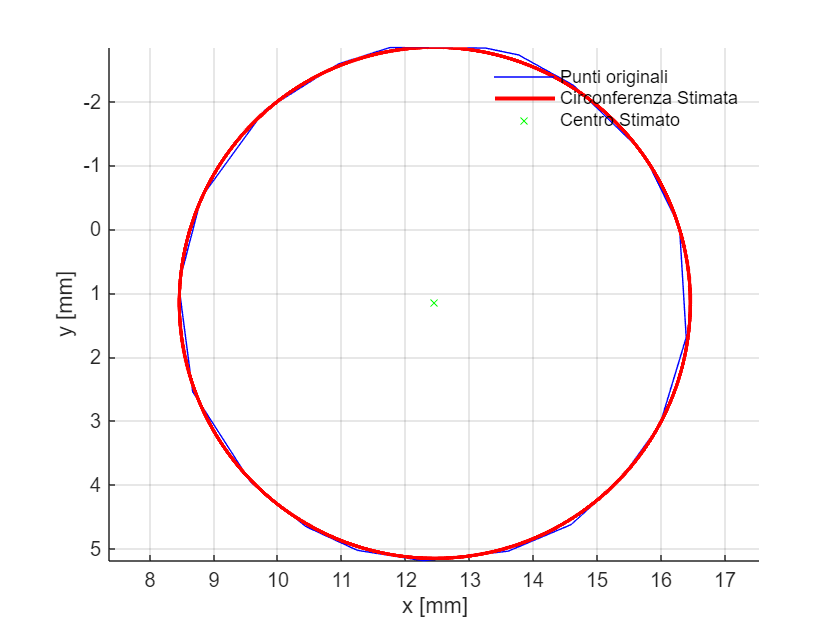

x = skeletonWorldCoordinates(:, 1);
y = skeletonWorldCoordinates(:, 2);

% Step 2: Costruisci il sistema lineare per trovare il centro
A = [2*x, 2*y, ones(size(x))];
b = x.^2 + y.^2;

% Risolvi il sistema con i minimi quadrati
params = A \ b;
xc = params(1); % Centro x
yc = params(2); % Centro y
R = sqrt(params(3) + xc^2 + yc^2); % Raggio

% Step 3: Genera i punti della circonferenza per il plot
theta = linspace(0, 2*pi, length(skeletonWorldCoordinates(:,2))*5);
xt = xc + R * cos(theta);
yt = yc + R * sin(theta);

% Step 4: Plot dei punti originali e della circonferenza
figure

hold on
plot(x, y, 'b-', 'DisplayName', 'Punti originali'); % Punti originali
plot(xt, yt, 'r-', 'LineWidth', 2, 'DisplayName', 'Circonferenza Stimata'); % Circonferenza
plot(xc, yc, 'gx', 'MarkerSize', 5, 'DisplayName', 'Centro Stimato'); % Centro

legend;
legend box off

xlabel('x [mm]');
ylabel('y [mm]');

% title(sprintf('Circonferenza Stimata: Centro (%.2f, %.2f), Raggio %.2f', xc, yc, R));
axis equal;
grid on;

% Inverti l'asse y
set(gca, 'YDir', 'reverse');

skeletonWorldCoordinates = [xt,yt];

% Salvo ogni variabile con il rispettivo nome nel folder 
variabili = {'skeletonWorldCoordinates'};
for i = 1:numel(variabili)
    varName = variabili{i};
    fileName = fullfile(folder_target, [varName, '.mat']);
    save(fileName, varName);
end

        2. 8

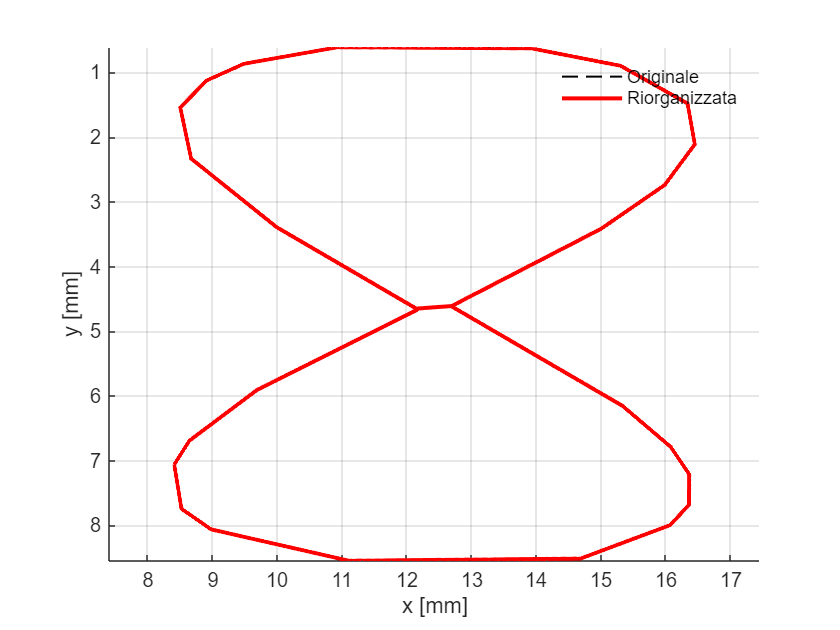

% Carica le coordinate (skeletonWorldCoordinates deve contenere le coordinate originali)
x = skeletonWorldCoordinates(:, 1); % Coordinate X
y = skeletonWorldCoordinates(:, 2); % Coordinate Y

% Indici noti dei punti centrali
index_center_1 = 626; % Primo punto centrale
index_center_2 = 3323; % Secondo punto centrale

% Suddividi le coordinate in segmenti basati sugli indici noti
segment_1 = 1:index_center_1; % Segmento 1: dall'inizio al primo punto centrale
segment_2 = index_center_1:index_center_2; % Segmento 2: tra i due punti centrali
segment_3 = index_center_2:length(x); % Segmento 3: dal secondo punto centrale alla fine

% Riorganizza i segmenti per ottenere la forma a 8
x_reorganized = [x(segment_1); flip(x(segment_2)); x(segment_3)];
y_reorganized = [y(segment_1); flip(y(segment_2)); y(segment_3)];

% Visualizza la figura originale e quella riorganizzata
figure;
plot(x, y, 'k--', 'LineWidth', 1); % Figura originale
hold on;
plot(x_reorganized, y_reorganized, 'r-', 'LineWidth', 2); % Figura riorganizzata

legend('Originale', 'Riorganizzata');
legend box off

xlabel('x [mm]');
ylabel('y [mm]');

% title(sprintf('Circonferenza Stimata: Centro (%.2f, %.2f), Raggio %.2f', xc, yc, R));
axis equal;
grid on;

% Inverti l'asse y
set(gca, 'YDir', 'reverse');
box off

skeletonWorldCoordinates = [x_reorganized, y_reorganized];

% Salvo ogni variabile con il rispettivo nome nel folder 
variabili = {'skeletonWorldCoordinates'};
for i = 1:numel(variabili)
    varName = variabili{i};
    fileName = fullfile(folder_target, [varName, '.mat']);
    save(fileName, varName);
end

% Salvo ogni variabile con il rispettivo nome nel folder 
variabili = {'skeletonWorldCoordinates'};
for i = 1:numel(variabili)
    varName = variabili{i};
    fileName = fullfile(folder_target, [varName, '.mat']);
    save(fileName, varName);
end

## COMPUTE ERRORS USER

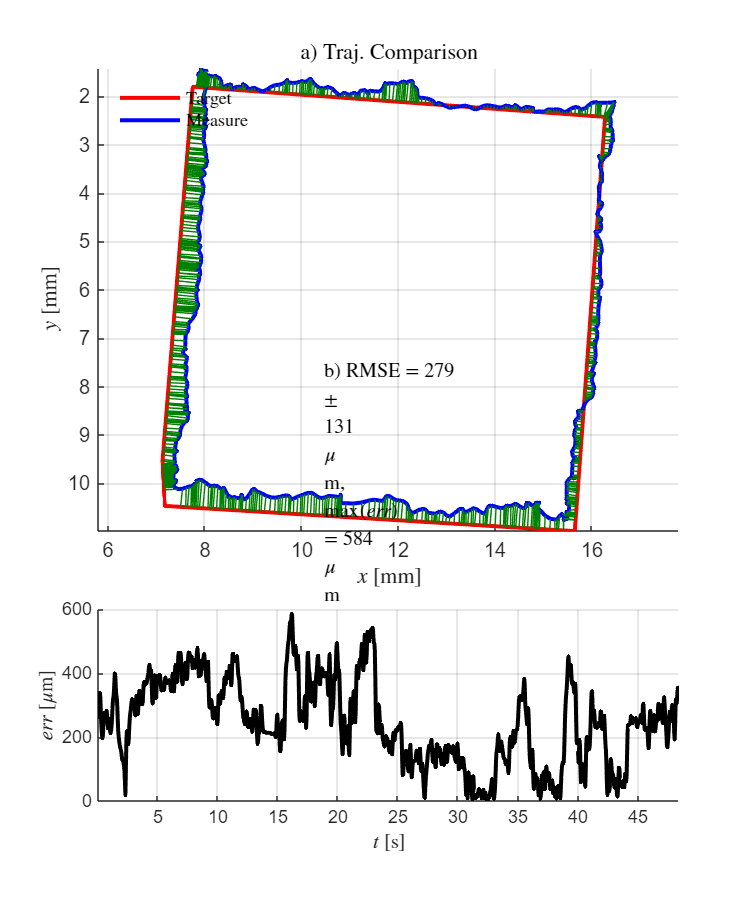

RMSE     = 279 ± 131 µm
max(err) = 584 µm


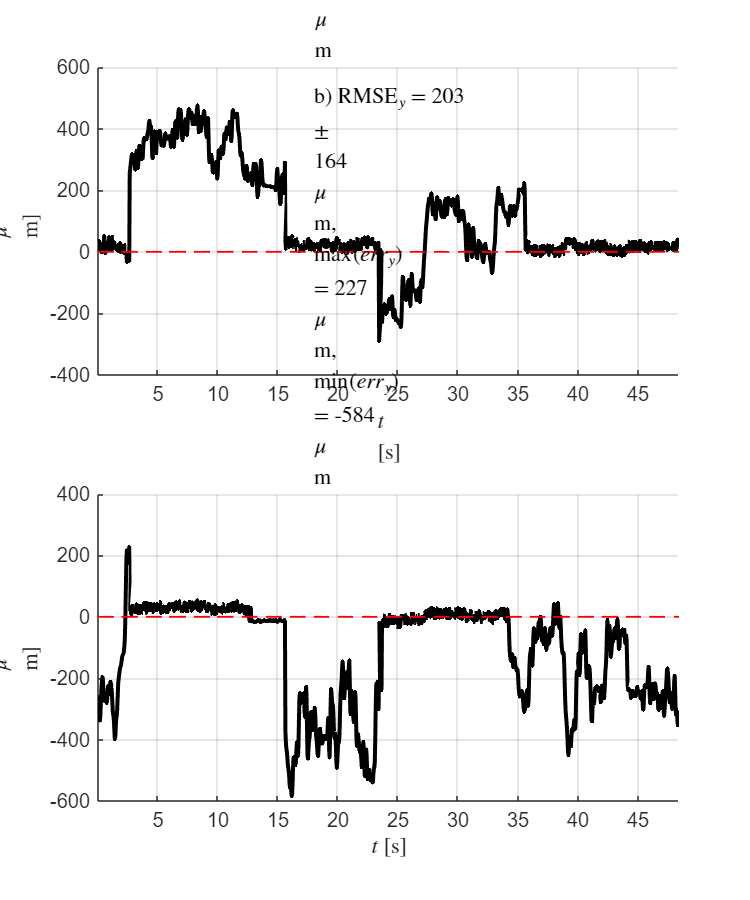

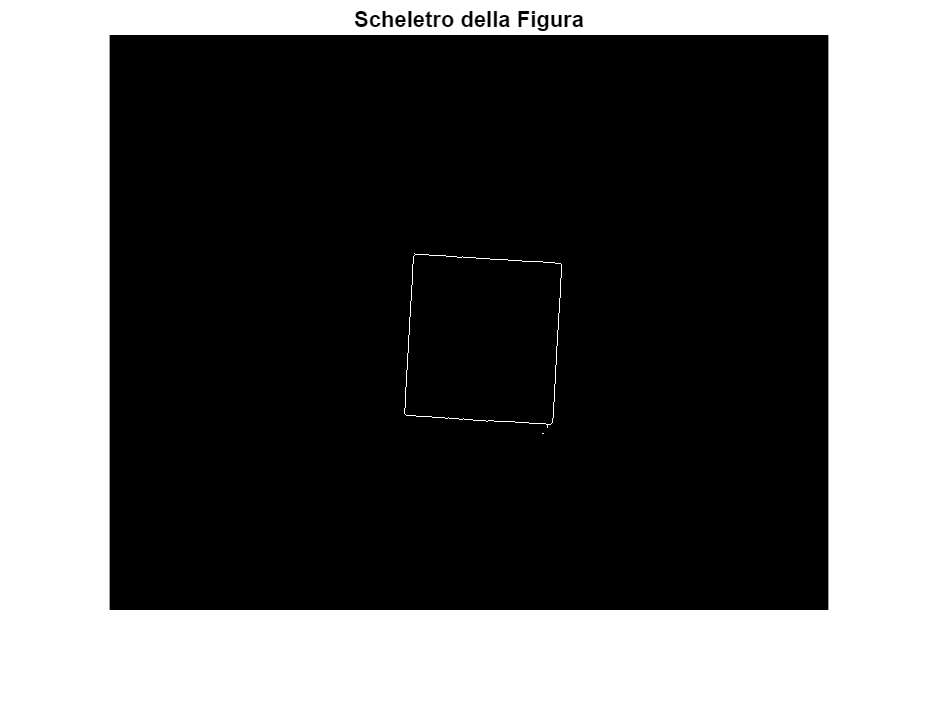

% t is time
xt = skeletonWorldCoordinates(:,1);
yt = skeletonWorldCoordinates(:,2);

t = (1:1:length(coords_matrix(:,2)))'/ video.FrameRate;
[rmse, std, err] = circ_rmse(xt, yt, laserWorldPoints_filtered(:,1) ,laserWorldPoints_filtered(:,2), t);